clear all; clc

### 1. Physical constants

G = 6.674*10^-11; %gravitational constant [m3⋅kg−1⋅s−2]
min_Bouncing_v = 0.15; %arbitrary minimum velocity after bouncing restitution [m/s]

### 2. User input for preset shapes

- Select state vector as initial condition: state_vector = [x y z vx vy vz] {m m m m/s m/s m/s}

- Select astronomical body:  Where: n=1 Earth; n=2 Toutatis; n=3 HW1; n=4 Bennu 

- Define coeffcient of restitution restcoef

- Define propagation time t_final [sec]

- Define body spin state: spin_state = n. Where: n=0 inertial; n=1 rotating

For a collection of sample orbits, see READ ME document.

state_vector = [0 2000 0 0.4766 0 0 ];  %Toutatis low altitude circular orbit

body = 3;                               %body selection

restCoef = 0.65;                        %coefficient of restituion at bouncing [-]

tfinal = 100000;                         %propagation time [sec]

spin_state = 0;                         %spin state [-]


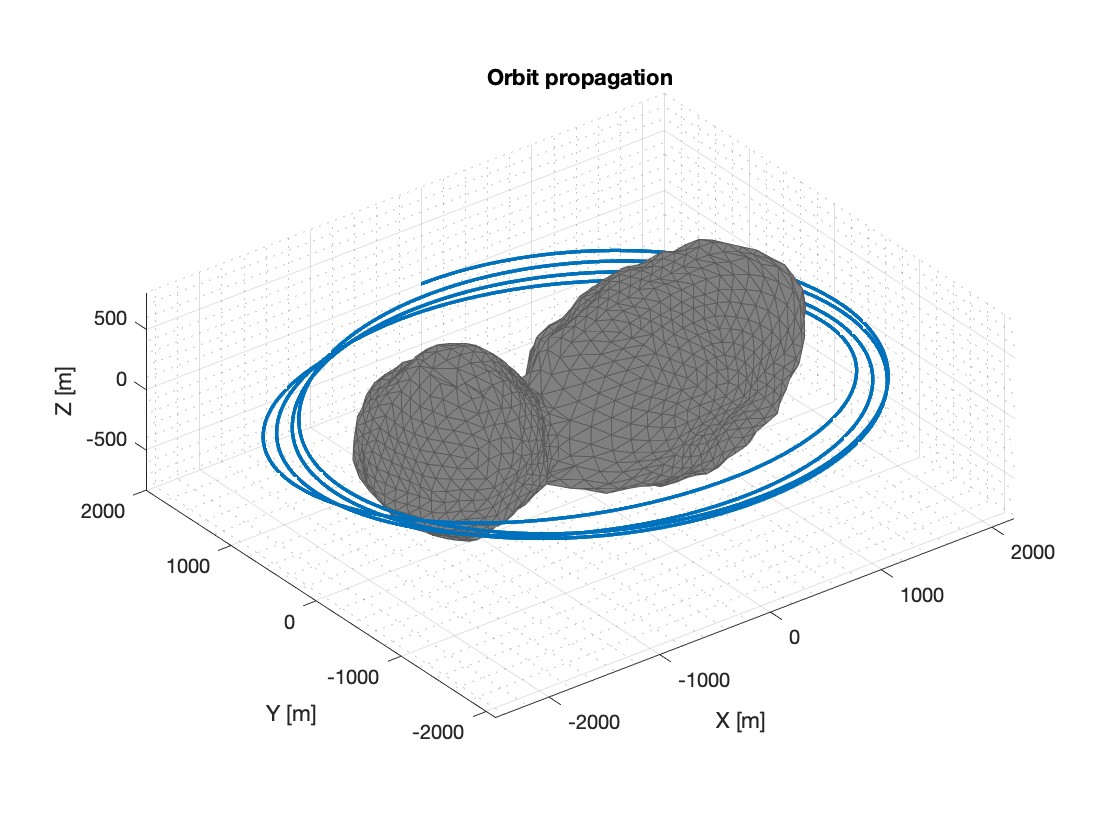

orbit = propagate(state_vector,body, tfinal, spin_state, restCoef, G, min_Bouncing_v);